# Parameter Effects - Unphysiological Regime a.k.a Parameter Sensitivity Analysis

AUTHOR: Kambadur Ananthamurthy

MAIN PROBLEM STATEMENT: Can we use concordance to make better predictions about detecting Time Cells?

DETAILS: 333 uniquely tagged synthetic datasets were analysed on the basis of a variety of numerical procedures (8 algorithms). Subsequently, these scores were used with either Bootstrapping or Otsu's Threshold based methods to classify cells.

Using the configuration for each of the 333 synthetic datasets we split the data based on "Hit Trial Ratio", "Event Width", "Imprecision", and "Noise", and compare the predictions of each of the 8 algorithms against ground truth.

close all
clear

tic

input.nCells = 135;
input.nAlgos = 8;
input.nMethods = 6;

workingOnServer = 1; %Only to select the batch for datasets

if workingOnServer == 1 %Bebinca
    % Synthetic Dataset Details
    input.gDate = 20210824; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210918; %consolidation date
    input.cRun = 1; %consolidation run number
    
elseif workingOnServer == 2 %Adama
    % Synthetic Dataset Details
    input.gDate = 20210903; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210911; %consolidation date
    input.cRun = 1; %consolidation run number
end

workingOnServer = 0; %Current
diaryOn         = 0;


% Directory config

if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/benchmarksDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/benchmarksDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end

% Operations
plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

% Load Synthetic Data
disp('Loading synthetic datasets ...')

Loading synthetic datasets ...


synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')

... done!



% Load Analysis Results
disp('Loading analysis results ...')

Loading analysis results ...


analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

... done!



input.removeNaNs = 0;
input.saveFolder = saveFolder;

%Labels
algoLabels = {'A-Boot', 'B-Boot', 'C-Boot', 'C-Otsu', 'D-Otsu', 'E-Otsu', 'F-Boot', 'F-Otsu'};
metricLabels = {'Recall', 'Precision', 'F1 Score'};
methodLabels = {'R2B', 'TI', 'Peak AUC/Std', 'PCA', 'SVM', 'Param. Eqs.'};
methodLabels2 = {'A', 'B', 'C', 'D', 'E', 'F'};
legends1 = {'TPR', 'FPR', 'TNR', 'FNR'};

figureDetails = compileFigureDetails(16, 2, 5, 0.2, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma

## Unphysiological Regime - Datasets 1 to 297 (PSA)

For this, consult setupSyntheticDataParams4.m (or configSynth.m)

There are N=3 randomizations per tag.

nShuffles = 3;

% Time Cell Percentage - Basic Order
iTCPb = nShuffles * (1:10);

% Time Cell Percentage - Random Order
iTCPr = nShuffles * (11:20);

% Hit Trial Ratio - Fixed Assignment, Fixed Order
iHTRfixedAfixedO = nShuffles * (21:30);

% Hit Trial Ratio - Fixed Assignment, Random Order
iHTRfixedArndO = nShuffles * (41:50);

% Hit Trial Ratio - Random Assignment, Fixed Order
iHTRrndAfixedO = nShuffles * (11:20);

% Hit Trial Ratio - Random Assignment, Random Order
iHTRrndArndO = nShuffles * (31:40);

% Event Widths - Fixed
iEWfixed = nShuffles * (61:67);

% Event Widths - 1 std. dev. variability
iEWvar = nShuffles * (68:74);

% Uniform Imprecision
iUImp = nShuffles * (75:84);

% Normal Imprecision
iNImp = nShuffles * (85:94);

% Noise
iNoise = nShuffles * (95:99);

## Time Cell Percentage - Basic Order

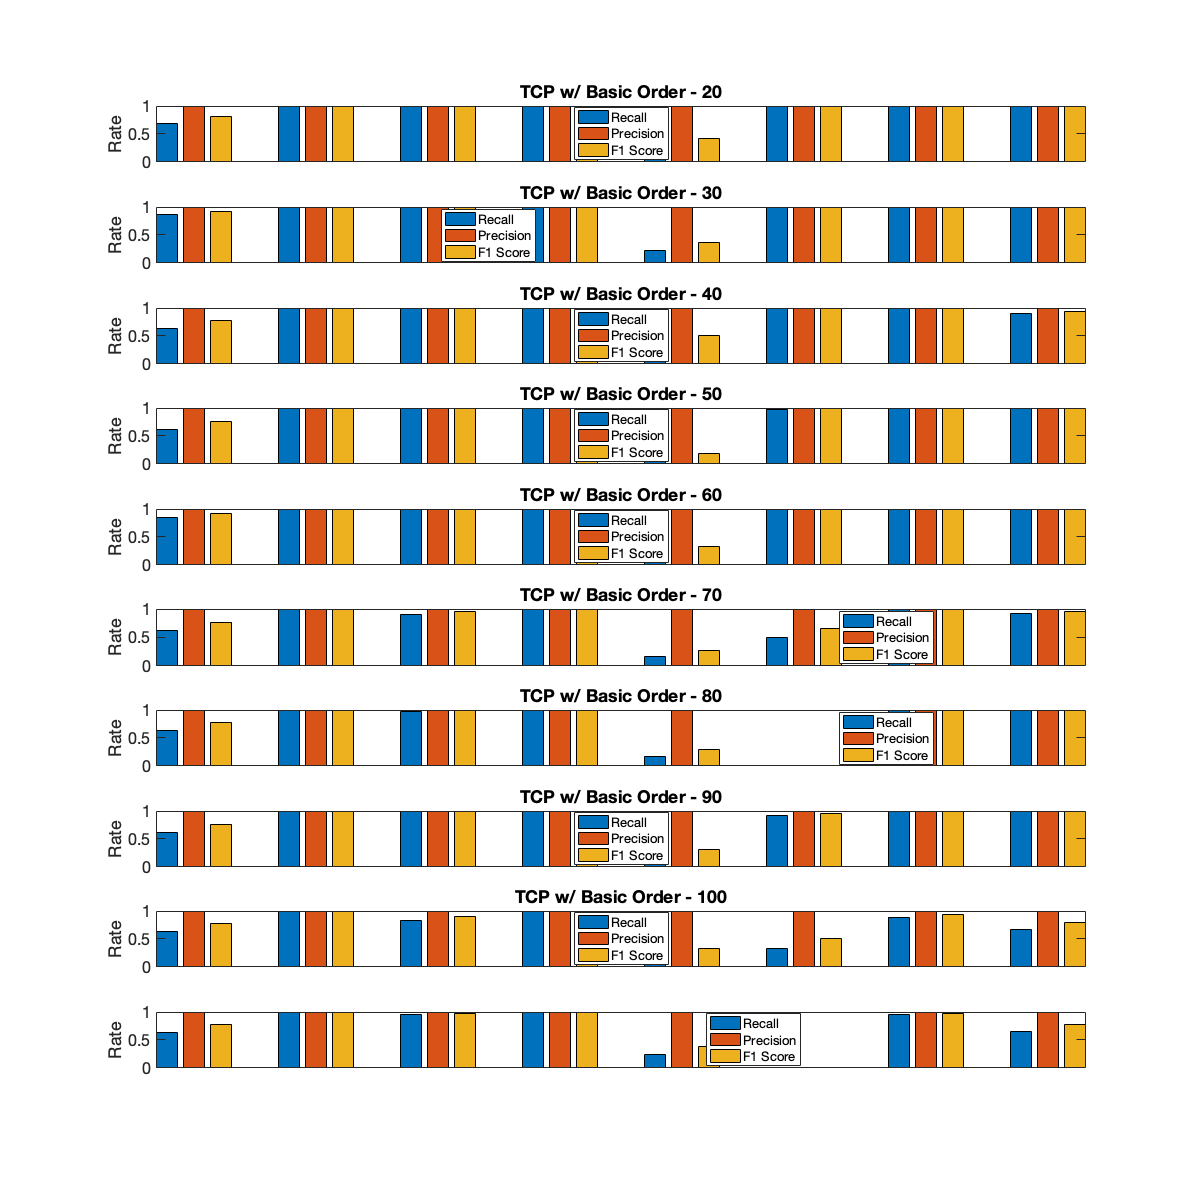

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'TCP w/ Basic Order - ';

valueList = (10:10:100);
valueListLabels = {'10%', '20%', '30%', '40%', '50%', '60%', '70%', '80%', '90%', '100%'};
nExpts = length(valueList);

nShuffles = 3;
fig1 = figure(1);
clf
set(fig1, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

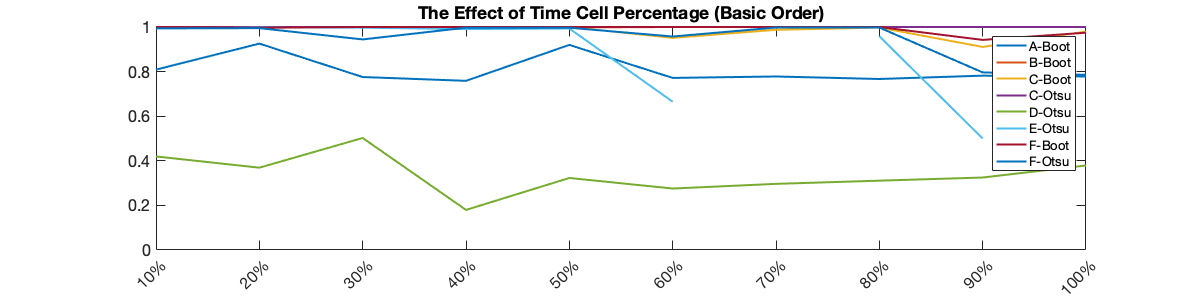


fig2 = figure(2);
clf
set(fig2, 'Position', [300, 300, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of Time Cell Percentage (Basic Order)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Time Cell Percentage - Random Order

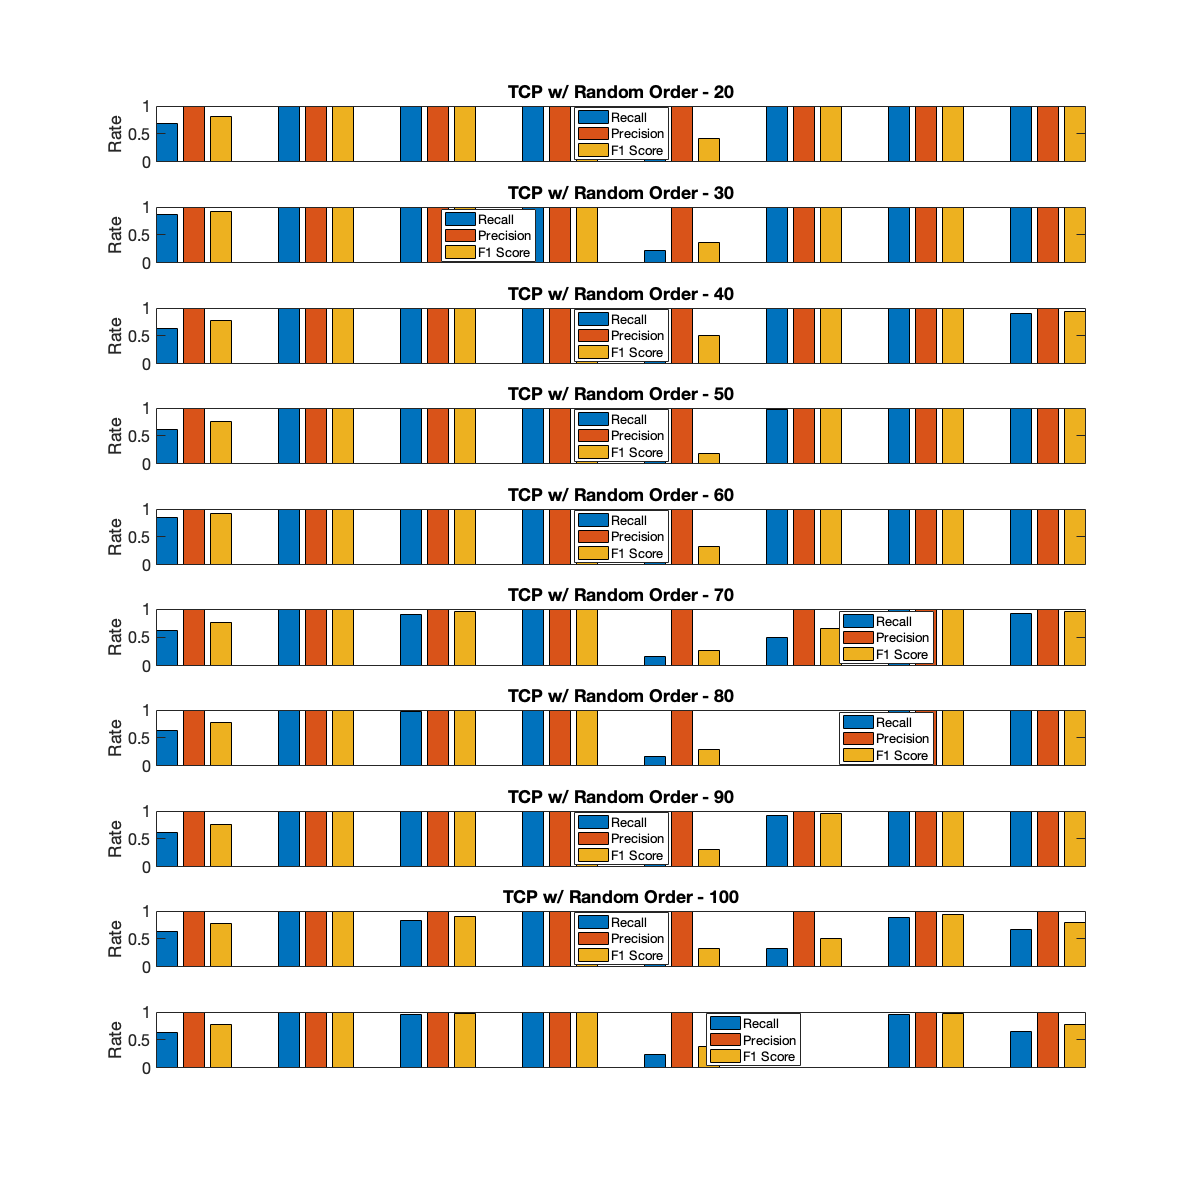

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'TCP w/ Random Order - ';

valueList = (10:10:100);
valueListLabels = {'10%', '20%', '30%', '40%', '50%', '60%', '70%', '80%', '90%', '100%'};
nExpts = length(valueList);

nShuffles = 3;
fig3 = figure(2);
clf
set(fig3, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

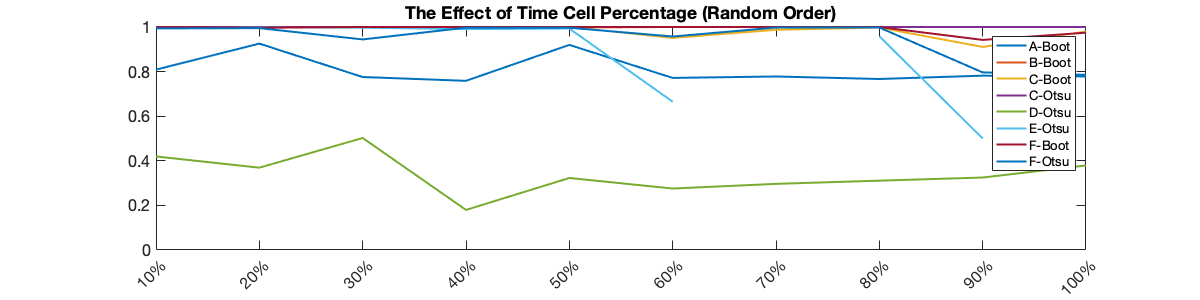


fig4 = figure(4);
clf
set(fig4, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of Time Cell Percentage (Random Order)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Hit Trial Ratio - Fixed Assignment, Fixed Order

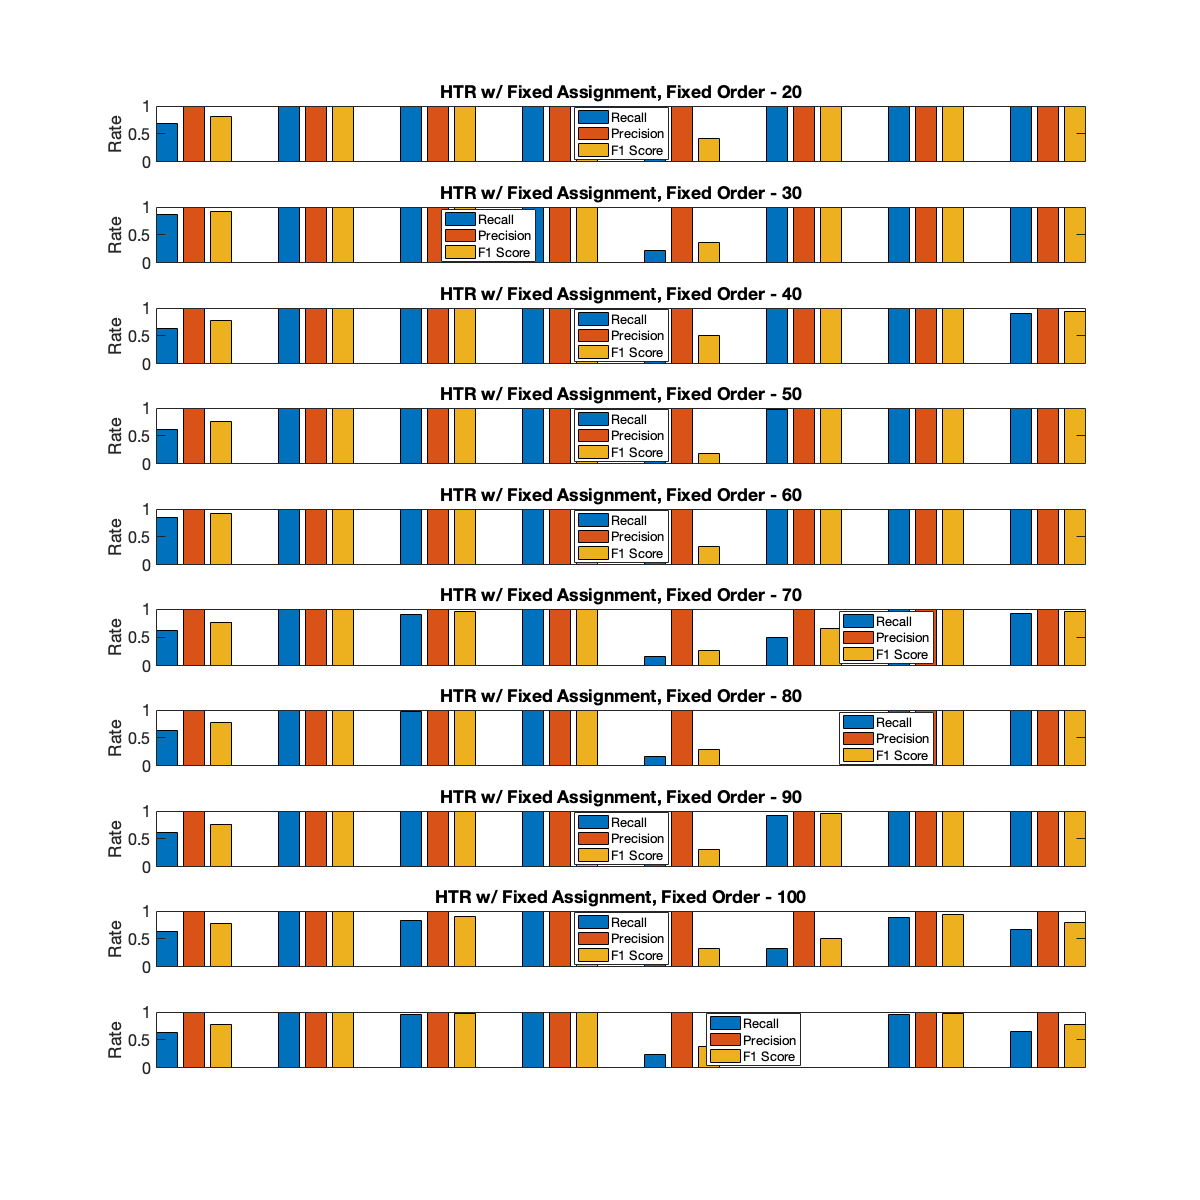

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'HTR w/ Fixed Assignment, Fixed Order - ';

valueList = (10:10:100);
valueListLabels = {'10%', '20%', '30%', '40%', '50%', '60%', '70%', '80%', '90%', '100%'};
nExpts = length(valueList);

nShuffles = 3;
fig5 = figure(5);
clf
set(fig5, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

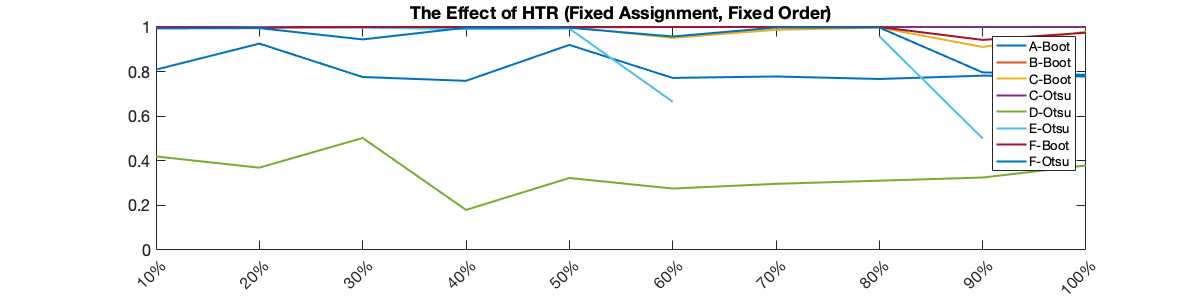


fig6 = figure(6);
clf
set(fig6, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of HTR (Fixed Assignment, Fixed Order)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Hit Trial Ratio - Fixed Assignment, Random Order

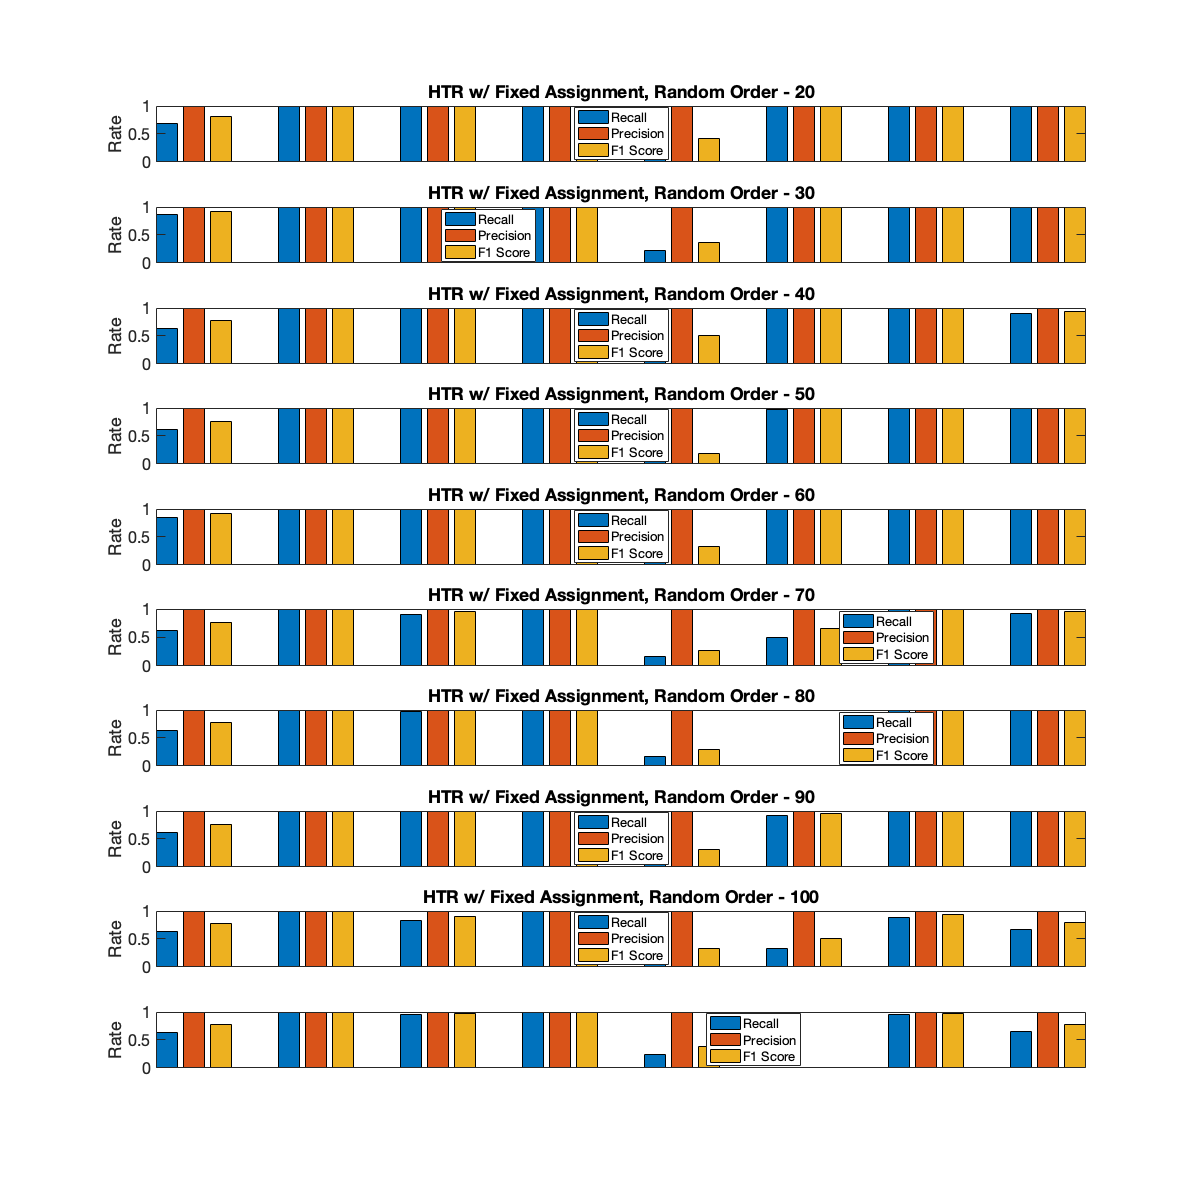

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'HTR w/ Fixed Assignment, Random Order - ';

valueList = (10:10:100);
valueListLabels = {'10%', '20%', '30%', '40%', '50%', '60%', '70%', '80%', '90%', '100%'};
nExpts = length(valueList);

nShuffles = 3;
fig7 = figure(7);
clf
set(fig7, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

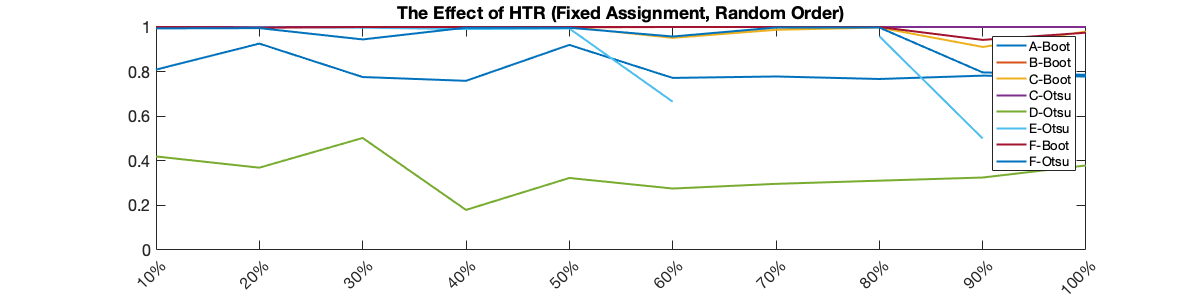


fig8 = figure(8);
clf
set(fig8, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of HTR (Fixed Assignment, Random Order)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Hit Trial Ratio - Random Assignment, Fixed Order

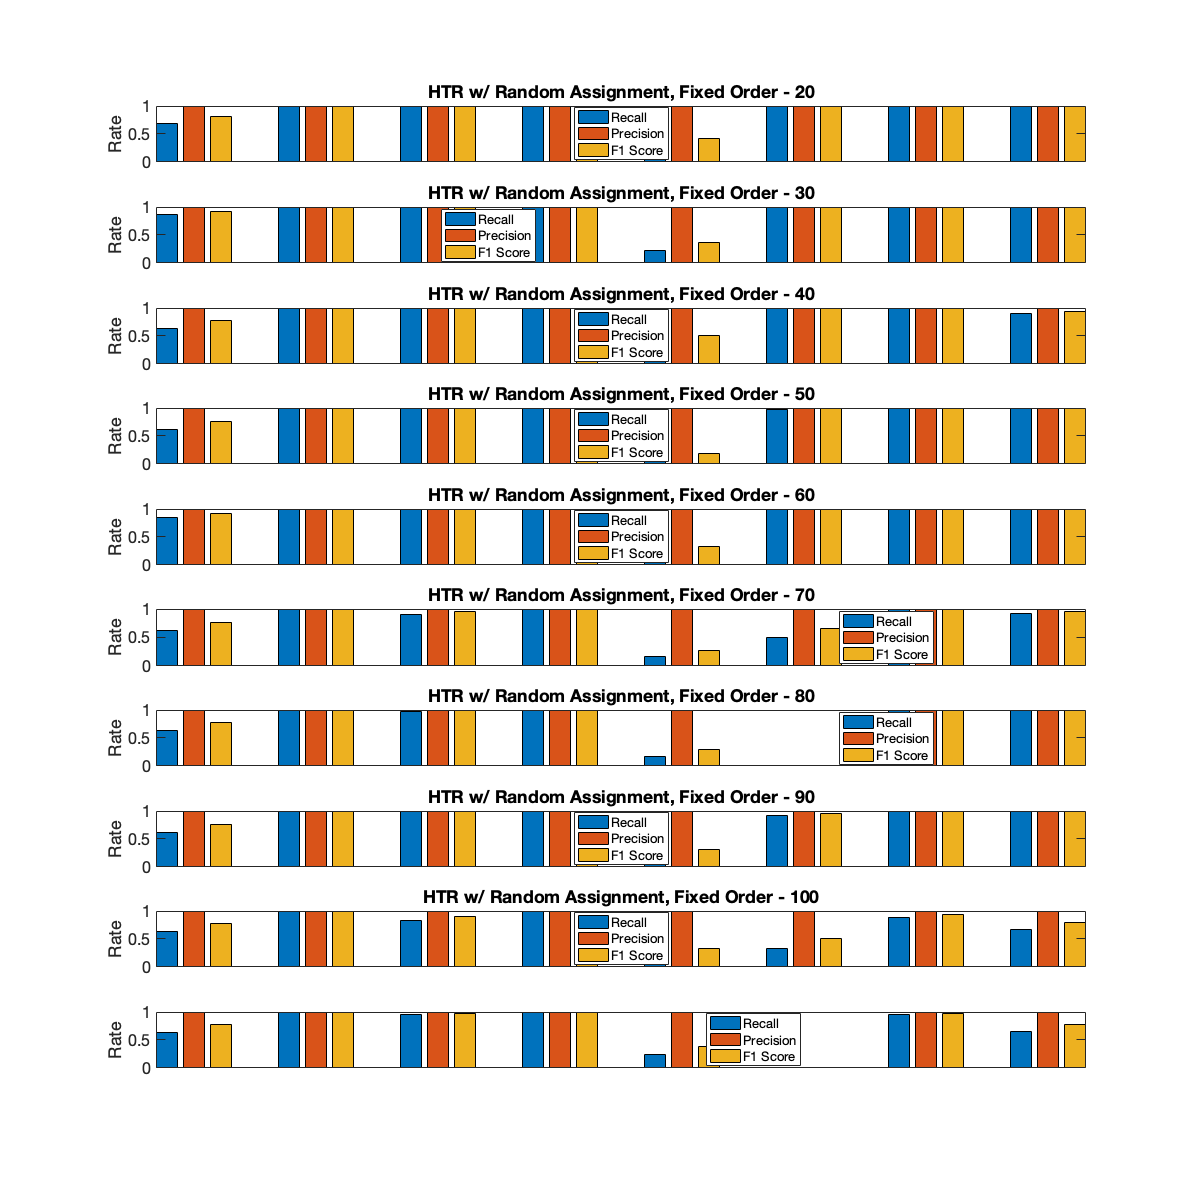

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'HTR w/ Random Assignment, Fixed Order - ';

valueList = (10:10:100);
valueListLabels = {'10%', '20%', '30%', '40%', '50%', '60%', '70%', '80%', '90%', '100%'};
nExpts = length(valueList);

nShuffles = 3;
fig9 = figure(9);
clf
set(fig9, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

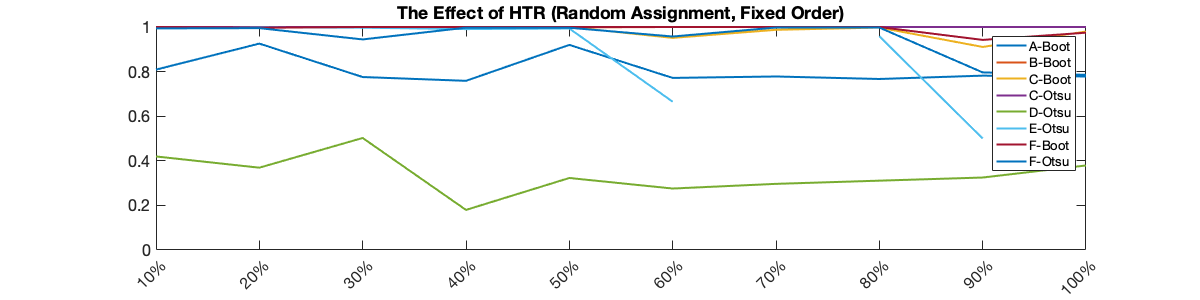


fig10 = figure(10);
clf
set(fig10, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of HTR (Random Assignment, Fixed Order)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Hit Trial Ratio - Random Assignment, Random Order

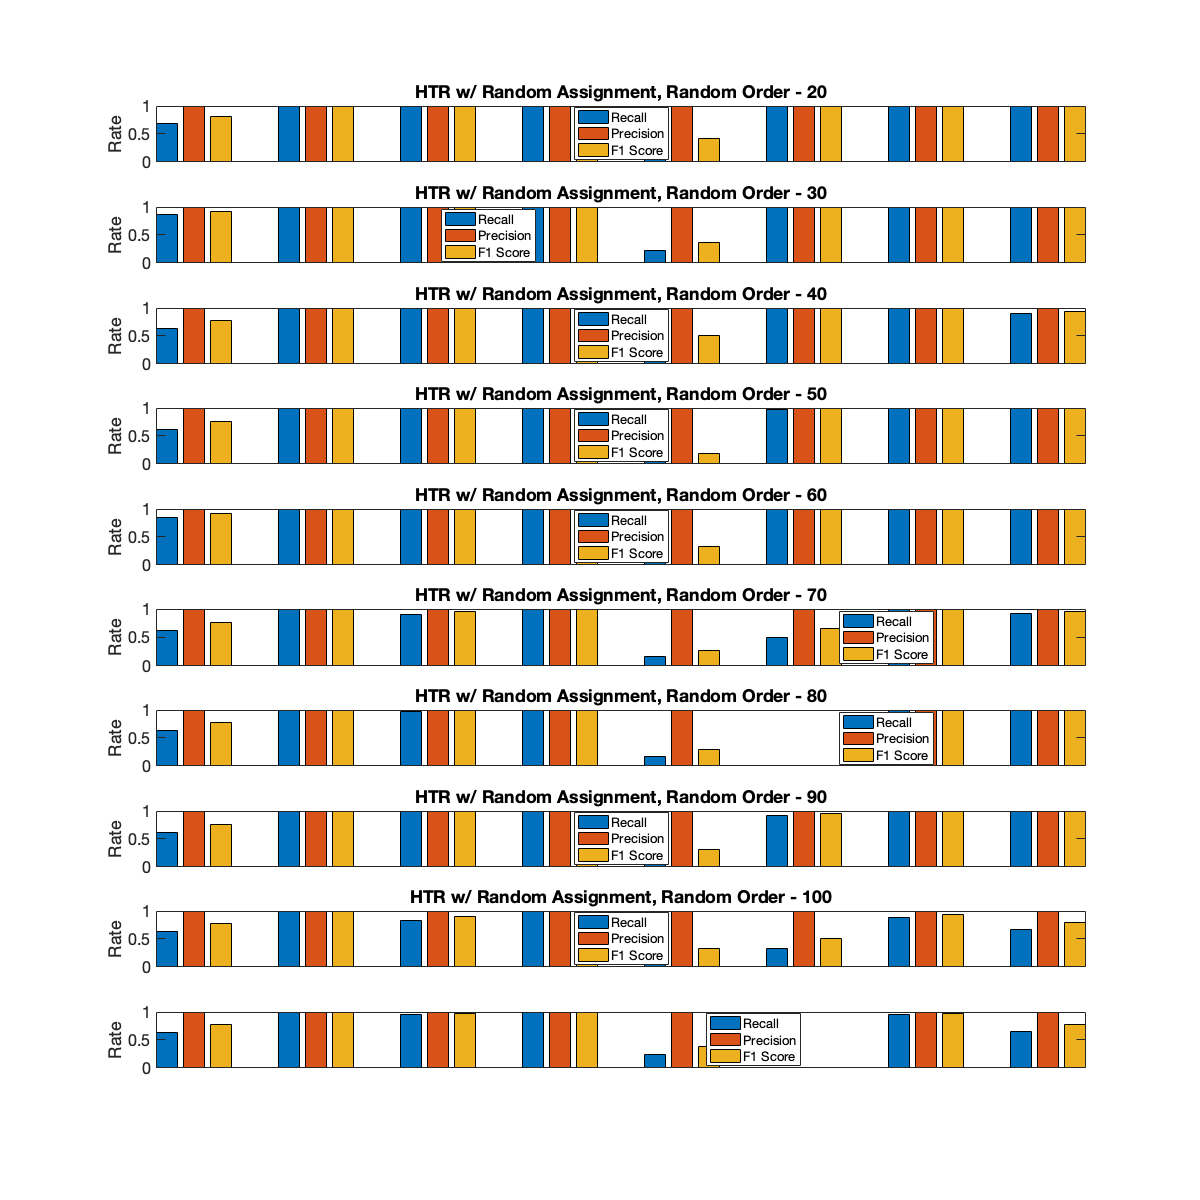

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'HTR w/ Random Assignment, Random Order - ';

valueList = (10:10:100);
valueListLabels = {'10%', '20%', '30%', '40%', '50%', '60%', '70%', '80%', '90%', '100%'};
nExpts = length(valueList);

nShuffles = 3;
fig11 = figure(11);
clf
set(fig11, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

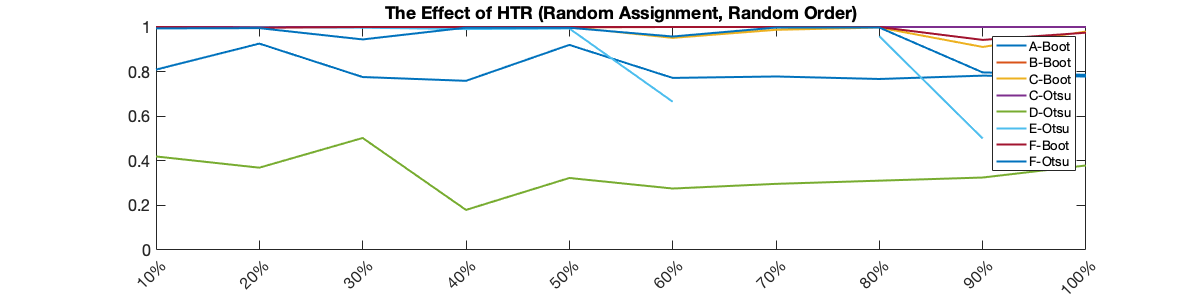


fig12 = figure(12);
clf
set(fig12, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of HTR (Random Assignment, Random Order)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Event Widths - Fixed

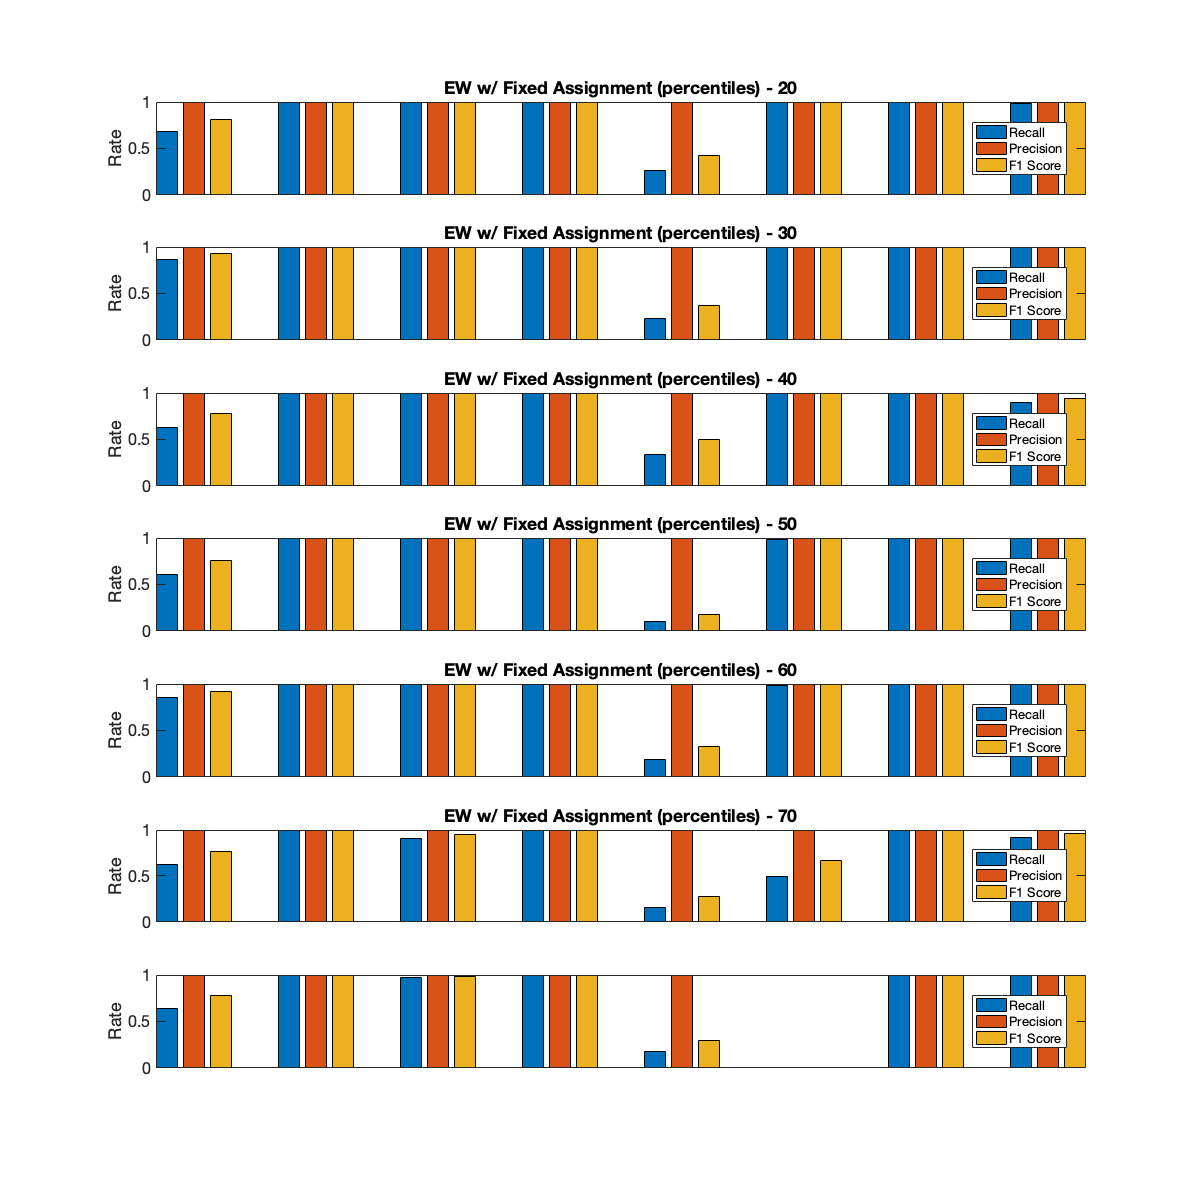

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'EW w/ Fixed Assignment (percentiles) - ';

valueList = (10:10:70);
valueListLabels = {'10th', '20th', '30th', '40th', '50th', '60th', '70th'};
nExpts = length(valueList);

nShuffles = 3;
fig13 = figure(13);
clf
set(fig13, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

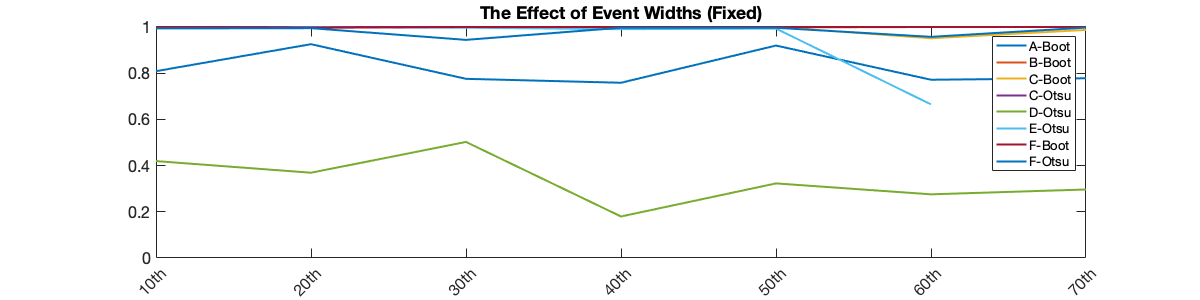


fig14 = figure(14);
clf
set(fig14, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of Event Widths (Fixed)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Event Widths - 1 std. dev. variability

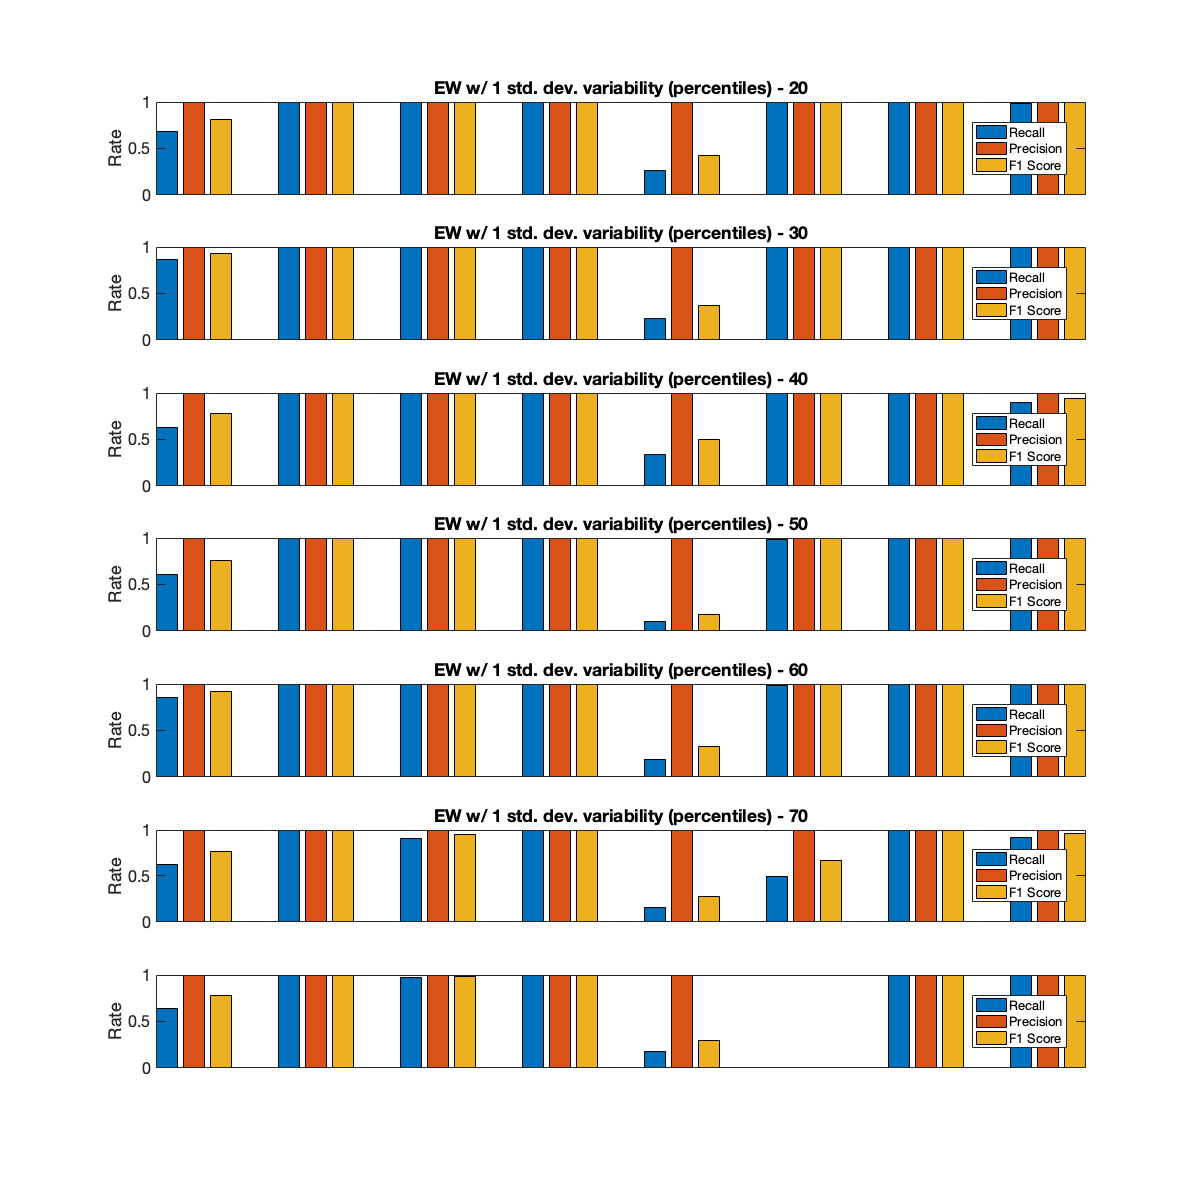

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'EW w/ 1 std. dev. variability (percentiles) - ';

valueList = (10:10:70);
valueListLabels = {'10th', '20th', '30th', '40th', '50th', '60th', '70th'};
nExpts = length(valueList);

nShuffles = 3;
fig15 = figure(15);
clf
set(fig15, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

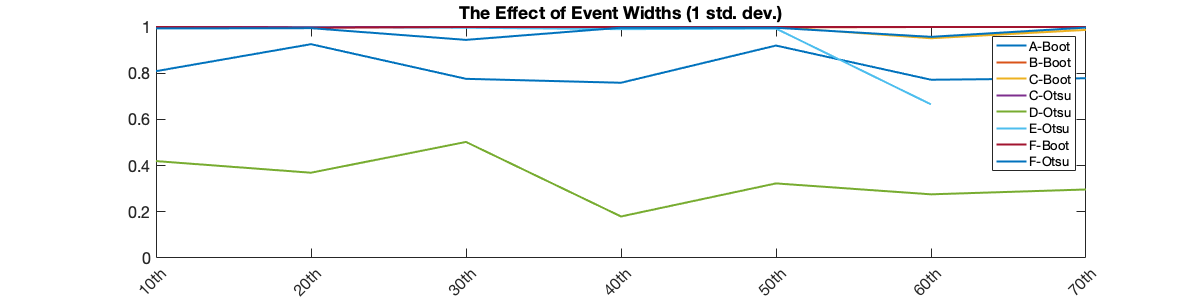


fig16 = figure(16);
clf
set(fig16, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of Event Widths (1 std. dev.)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Uniform Imprecision

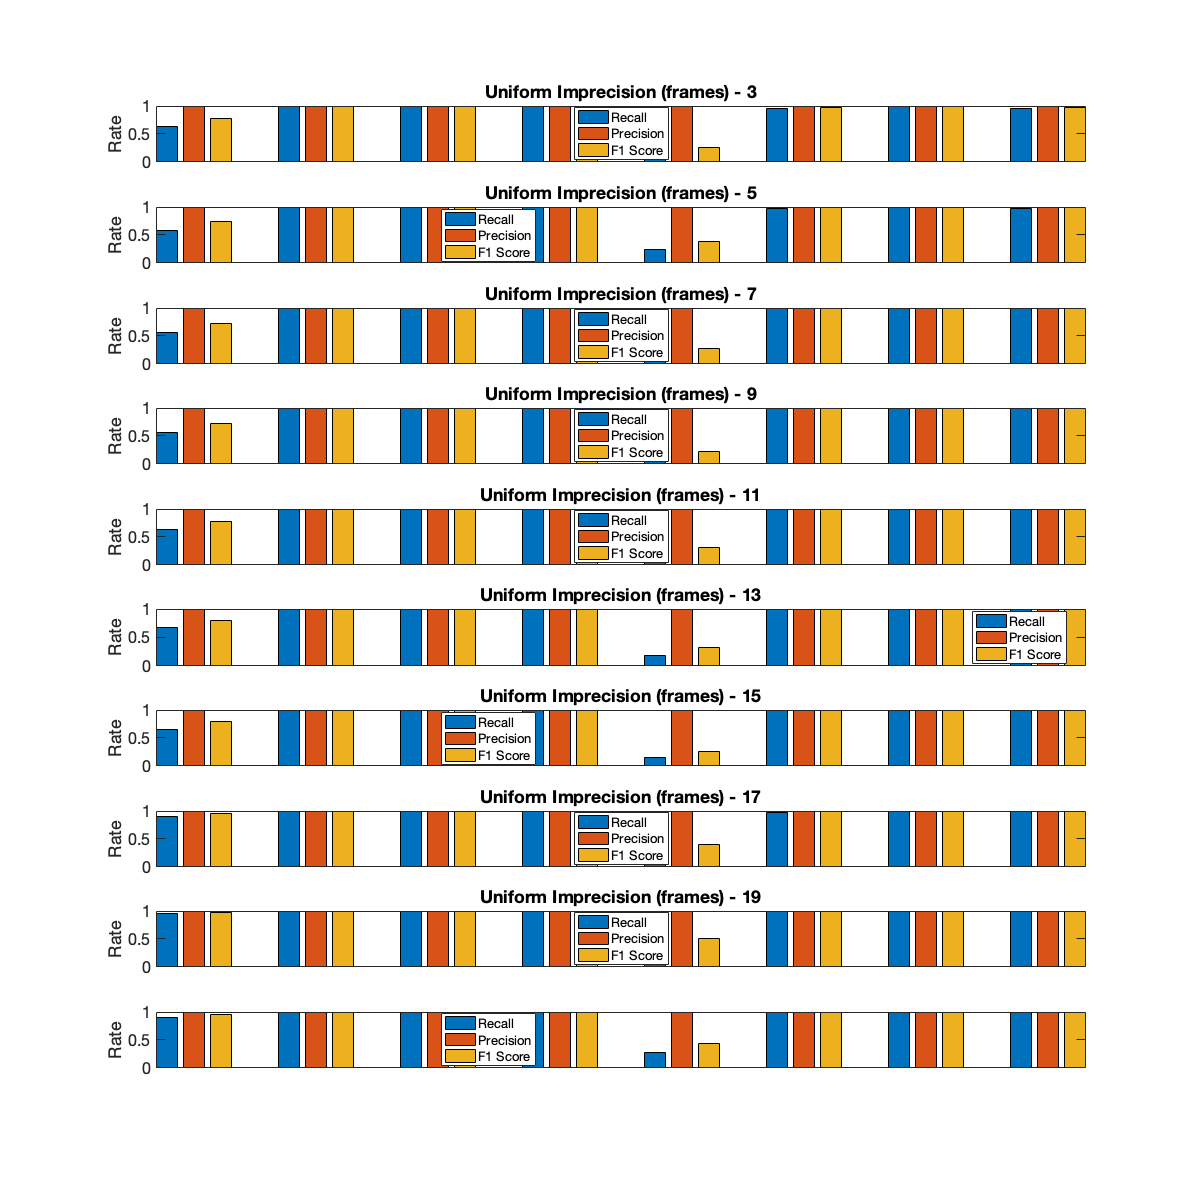

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'Uniform Imprecision (frames) - ';

valueList = (1:2:20);
valueListLabels = {'1', '3', '5', '7', '9', '11', '13', '15', '17', '19'};
nExpts = length(valueList);

nShuffles = 3;
fig17 = figure(17);
clf
set(fig17, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

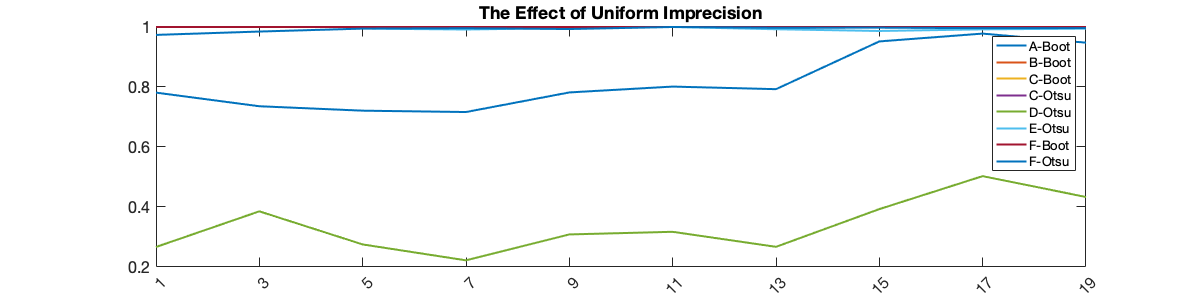


fig18 = figure(18);
clf
set(fig18, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of Uniform Imprecision', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Normal Imprecision

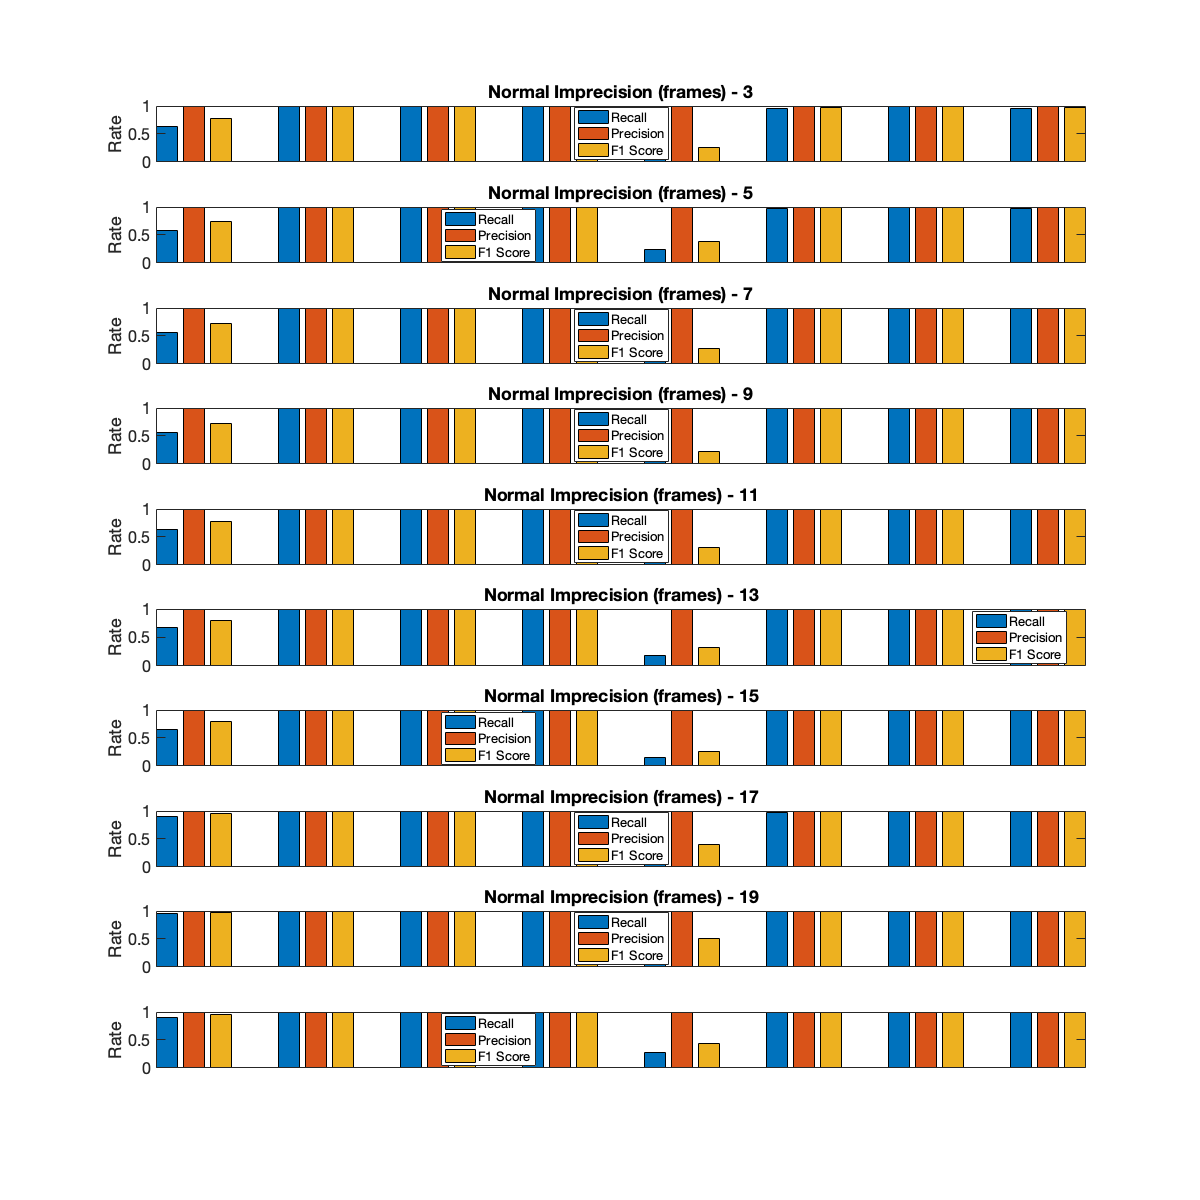

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'Normal Imprecision (frames) - ';

valueList = (1:2:20);
valueListLabels = {'1', '3', '5', '7', '9', '11', '13', '15', '17', '19'};
nExpts = length(valueList);

nShuffles = 3;
fig19 = figure(19);
clf
set(fig19, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

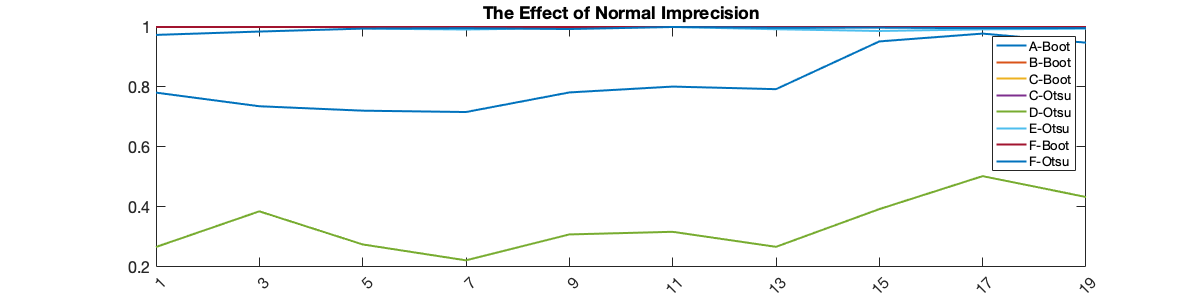


fig20 = figure(20);
clf
set(fig20, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of Normal Imprecision', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)

## Noise

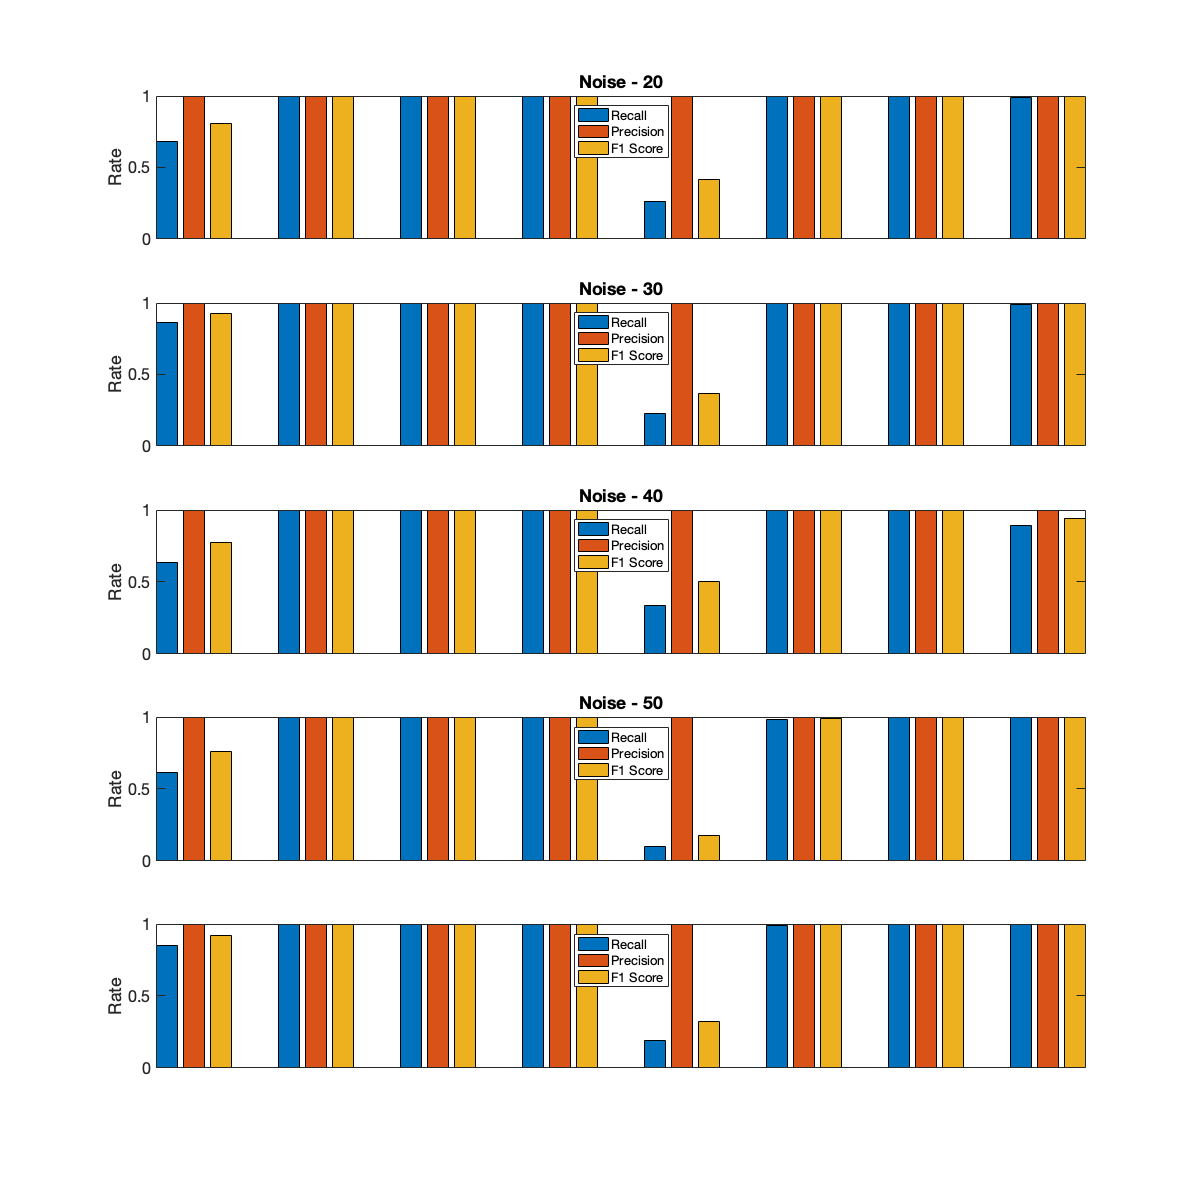

Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!
Creating Confusion Matrix ...
... done!


mainBarplotTitle = 'Noise - ';

valueList = (10:10:50);
valueListLabels = {'10', '20', '30', '40', '50'};
nExpts = length(valueList);

nShuffles = 3;
fig21 = figure(21);
clf
set(fig21, 'Position', [100, 100, 1200, 1200])
results3Line = zeros(input.nAlgos, nExpts);
for expt = 1:nExpts
    iStart = valueList(expt);
    iSelected = iStart: (iStart + nShuffles -1);
    [Y, X] = developConfusionMatrix4Effects(input, sdo_batch, cData, iSelected);
    %[results1, results2, results3] = compareAgainstTruth(X, Y, input);
    [~, ~, results3] = compareAgainstTruth(X, Y, input);
    title([mainBarplotTitle, num2str(valueList(expt))], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    subplot(nExpts, 1, expt)
    bar(results3);
    xlim([0, 2])
    axis tight
    % title(sprintf('Performance Evaluation (N=%i)', input.nDatasets), ...
    % 'FontSize', figureDetails.fontSize, ...
    % 'FontWeight', 'bold')
    ylabel('Rate', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels(algoLabels)
    xtickangle(45)
    set(gca,'xtick',[])
    lgd = legend(metricLabels, ...
        'Location', 'best');
    lgd.FontSize = figureDetails.fontSize-3;
    set(gca, 'FontSize', figureDetails.fontSize)
    
    results3Line(:, expt) = results3(:, 3);
end

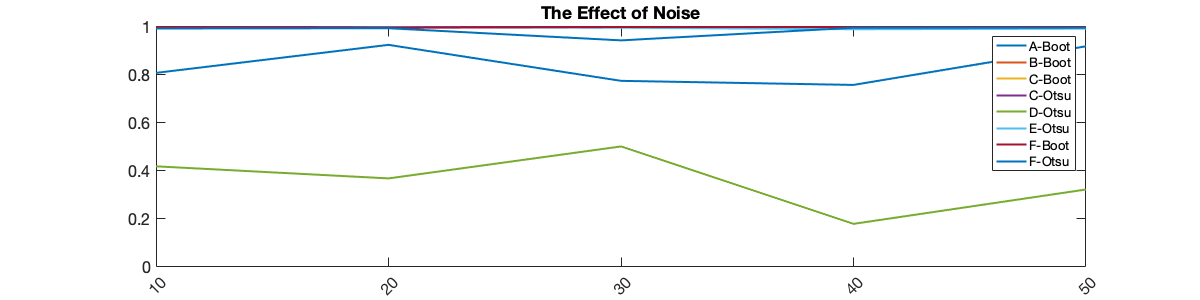


fig22 = figure(22);
clf
set(fig22, 'Position', [100, 100, 1200, 300])
plot(results3Line', ...
    'LineWidth', figureDetails.lineWidth)
title('The Effect of Noise', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xticks([1:nExpts])
xticklabels(valueListLabels)
xtickangle(45)
lgd = legend(algoLabels);
lgd.FontSize = figureDetails.fontSize-3;
set(gca, 'FontSize', figureDetails.fontSize)